## Load the data set

load data_R_PBE.mat

## Slice figure for paper (Fig. 5b)

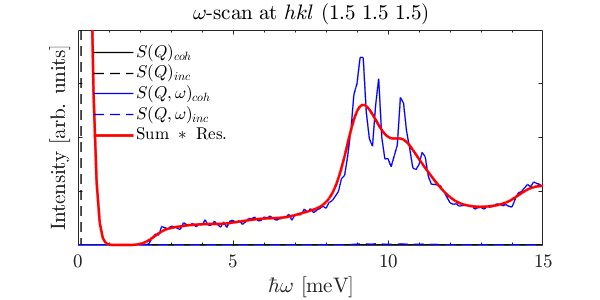

f=figure;
set(f,'Position',[500 500 600 300]);
set(gcf,'color','w');

hold on 
h(1)=plot(maps.w,maps.sq_coh,'-k','linewidth',1);
h(2)=plot(maps.w,maps.sq_inc,'--k','linewidth',1);
h(3)=plot(maps.w,maps.sqw_coh,'-b','linewidth',1);
h(4)=plot(maps.w,maps.sqw_inc,'--b','linewidth',1);
h(5)=plot(maps.w_conv,maps.sum_conv,'-r','linewidth',2);
hold off 

xlim([0 15]);
ylim([0 0.04]);

set(gca,'fontsize',14,'TickLabelInterpreter','latex','XMinorTick','on','YTickLabel',[]);
xlabel('$\hbar\omega$~[meV]','interpreter','latex');
ylabel('Intensity~[arb. units]','interpreter','latex');
legend(h,{'$S(Q)_{coh}$','$S(Q)_{inc}$','$S(Q,\omega)_{coh}$','$S(Q,\omega)_{inc}$','Sum$~*~$Res.'},...
    'interpreter','latex','box','off','location','northwest');
title('$\omega$-scan at $hkl$~(1.5 1.5 1.5)','interpreter','latex');

box on;